% EDP tutorial with a 2d example
clear all
close all
rng('default');
rng(1);

% time-series generation
disp('*****************************************************')

*****************************************************


disp('Data generation and structure')

Data generation and structure


disp('*****************************************************')

*****************************************************


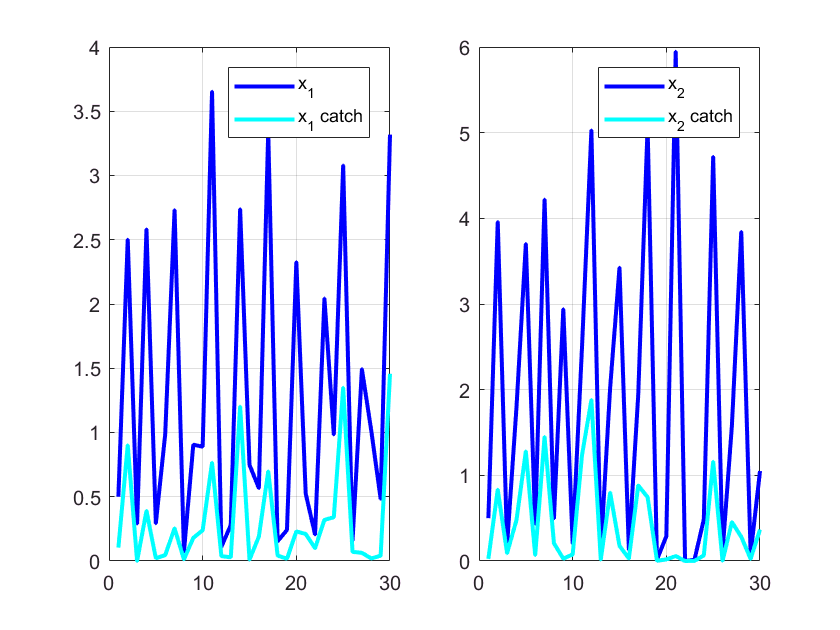


% Time-series length
T = 30;

% default EDM structure
[mdlstruct] = init_mdl_struct(2); % the input is the number of available species data

% data generation using a ricker model
% param={[0.1 0.1],[3 0.5; 0.8 3],[3 3]}; % ricker model parameters
param={[0.1 0.1],[2 0.5; -0.3 2],[3 3]}; % ricker model parameters
mdlstruct.model = @(x,u,is_det) dyn_ricker(x,u,is_det,param);


% random control between 0 and 0.5
u = rand(T,2)/2;

% data generation
[mdlstruct.data,mdlstruct.control_data] =  generate_data(mdlstruct.model,[0.5 0.5],u,T);

%different kinds of control exist, we need to specify which one we use here
mdlstruct.control_type =  'rate';
mdlstruct.control_param =  [1 1]; % both  dimensions are fully controlled

% data display
data_show(mdlstruct)



% we specify the number of lags used here
% here, we specify the number of time lags used for each variables
% 0 means that the variable is not used in the prediction
mdlstruct.n_lags = [1 1];

% GP regression
disp('*****************************************************')

*****************************************************


disp('GP fitting')

GP fitting


disp('*****************************************************')

*****************************************************


**********************************************************
Negative log likelihood: -32.6561     -47.6177
 
Lengthscale parameters:
  0.4741     0.23842
0.021911      1.3452
 
Scaled In-Sample error: 0.0028896  0.00053618
 
Scaled Out-of-Sample error: 0.0044266   0.0014306
 
**********************************************************


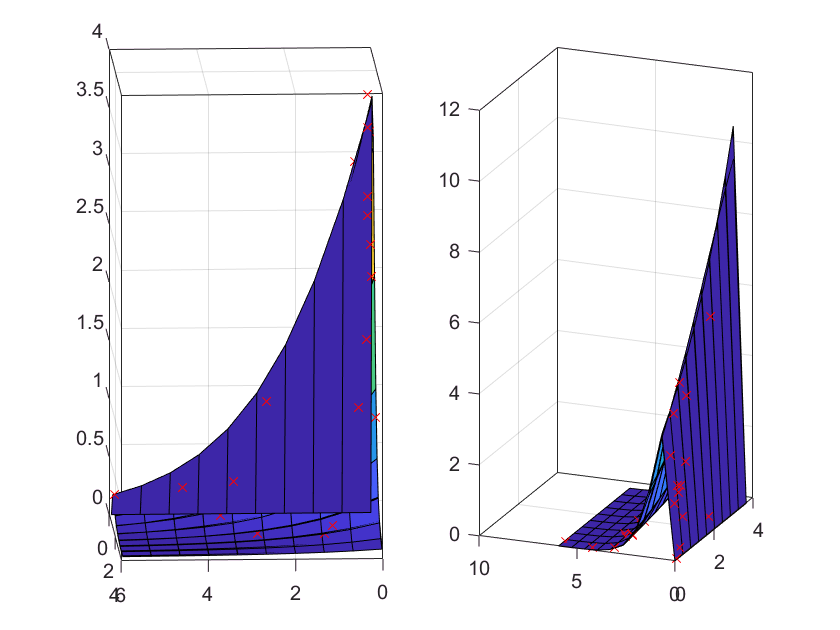

% this step can be skipped if a model already exists, otherwise a GP is
% fitted to the data
% fills the field mdlstruct.model with the fitted gp
% fills the field mdlstruct.model_stats with statistics computed during the
% GP regression

% default gp structure
mdlstruct.gp = init_gp();

% we now fit the gp with the data in mdlstruct
mdlstruct = fit_gp(mdlstruct);

% gp display
gp_show(mdlstruct)

% Optimal control problem
disp('*****************************************************')

*****************************************************


disp('  Optimal control problem structure creation')

  Optimal control problem structure creation


disp('*****************************************************')

*****************************************************



% Discount factor
optstruct.discount_factor=0.95;

% Objective weights
optstruct.weights = [0.5 0.5];


% Reward function
% The instantaneous reward function is a handle function.
% The input are the current variables, the controls and the weight for each
% dimension
% The output are the total weighted reward, the unweighted reward on each
% dimension, and the weighted reward on each dimension

%>>> Example 1 <<<<
% use of an existing function
optstruct.reward = @(x,u,w) reward_harvest_all(x,u,w);

% Temporal difference learning
disp('*****************************************************')

*****************************************************


disp('EDP using Temporal difference learning')

EDP using Temporal difference learning


disp('*****************************************************')

*****************************************************


% default  td structure
dpstruct=init_td(mdlstruct);

%  run the td algorithm, using the gp regression
 [dpstruct] = td_learning(mdlstruct,optstruct,dpstruct,'gp');

 % control maps
 disp('Control maps given by the EDP algorithm')

Control maps given by the EDP algorithm


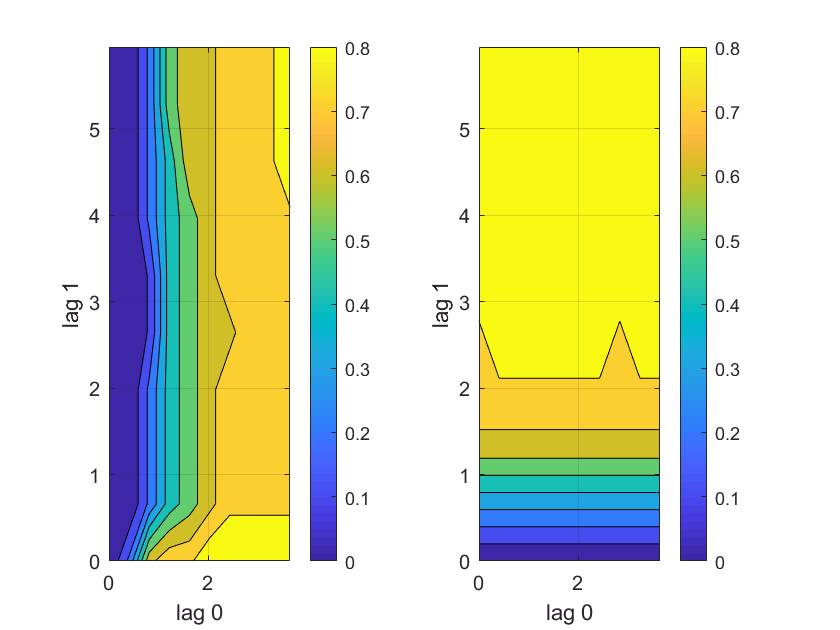

td_show(mdlstruct,optstruct,dpstruct)


% controlled trajectories
t_max = 50; % time length
n_traj = 10; % number of trajectories
start_x = 'last'; % starting point
is_disp = 1; % display the trajectories result
 disp('Controlled trajectories following the EDP policy')

Controlled trajectories following the EDP policy


**********************************************************
Theorical value: 55.3522
 
Simulated mean value: 54.815
 
**********************************************************


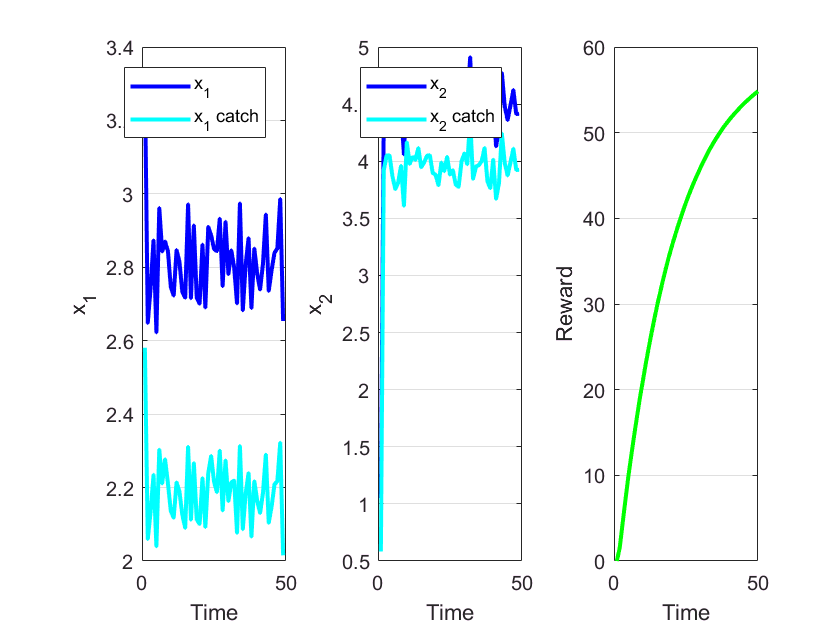

traj = sim_trajectories(mdlstruct,optstruct,dpstruct,t_max,n_traj,start_x,is_disp);

% Pareto front
disp('*****************************************************')

*****************************************************


disp('Pareto front')

Pareto front


disp('*****************************************************')

*****************************************************


**********************************************************
Theorical value: 39.255
 
Simulated mean value: 58.5322
 
**********************************************************
**********************************************************
Theorical value: 71.4494
 
Simulated mean value: 82.9192
 
**********************************************************
**********************************************************
Theorical value: 1.2047
 
Simulated mean value: 1.1776
 
**********************************************************
**********************************************************
Theorical value: 1.1023
 
Simulated mean value: 1.0561
 
**********************************************************
**********************************************************
Theorical value: 1.0139
 
Simulated mean value: 0.97249
 
**********************************************************
**********************************************************
Theorical value: 1.0009
 
Simulated mean value: 0.98951
 
****

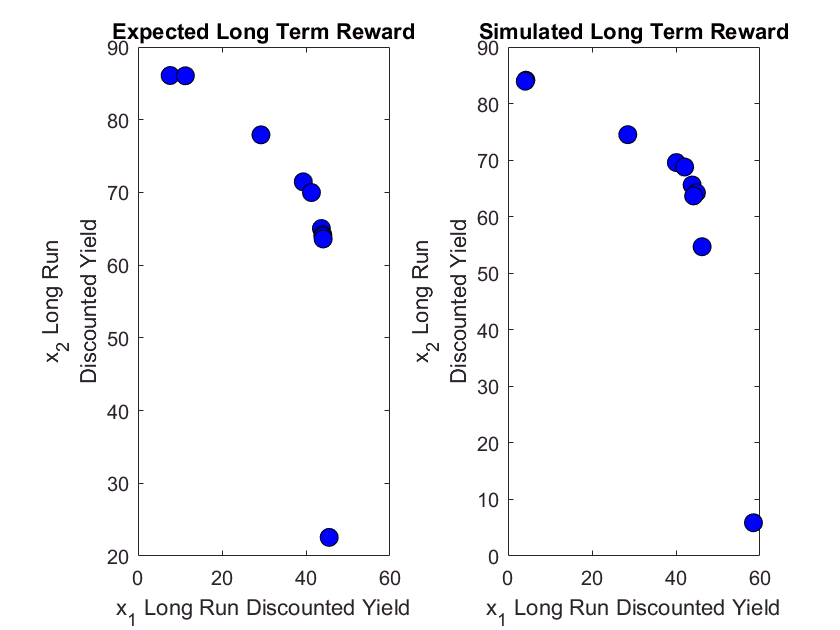

n_pareto = 10;
pareto = pareto_front(mdlstruct,optstruct,dpstruct,n_pareto,'gp');


% % control map for different Pareto weights
% td_show(mdlstruct,pareto.optstruct{1},pareto.dpstruct{1})
% td_show(mdlstruct,pareto.optstruct{end},pareto.dpstruct{end})
